# Seminar 2

## PROBLEM 13

File SM22_Seminar_2_Head_Brothers.xlsx contains measurements of the length and breadth of the heads of pairs of adult brothers in 25 randomly sampled families. We wish to analyze this dataset with techniques that assume multivariate Gaussianity:

% Importing from Seminar 1
function m = smean(pop)
    m = sum(pop, 1) / length(pop);
end

function s = sstd(pop)
    s = (pop-smean(pop))'*(pop-smean(pop)) / (length(pop)-1);
end

% Importing table

filename = 'semi2/SM22_Seminar_2_Head_Brothers.xlsx';
% check that working directory is ME-2024
raw = readtable(filename);

### a) Assess whether each of the 4 dimensions of these data is normally distributed.

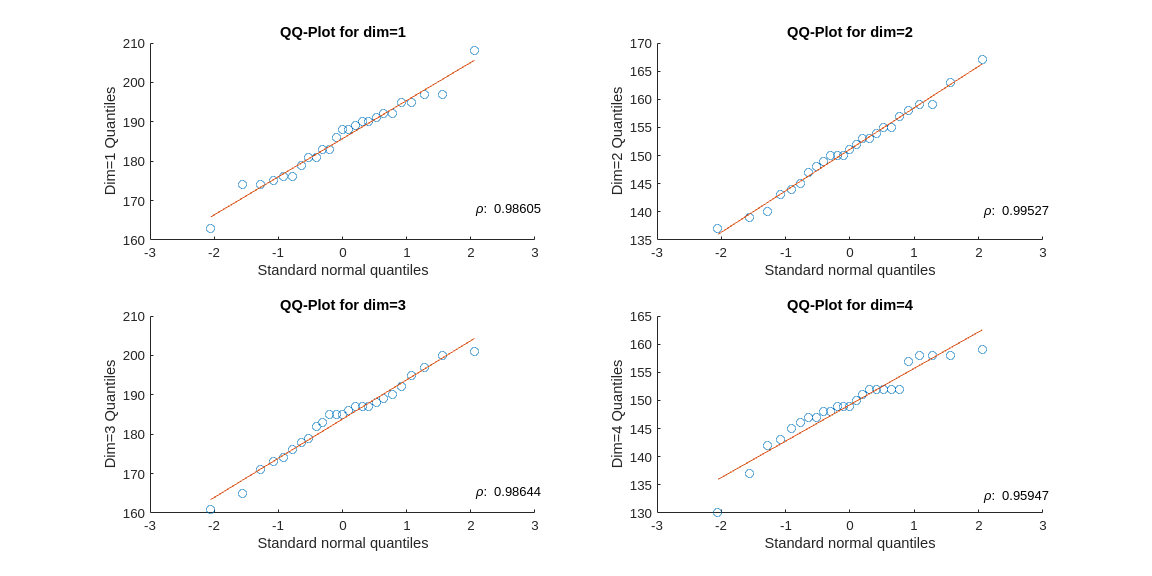

data = raw{:, 2:5};
alpha = 0.05;

cla; clf;
qq_plot(data);


disp(['With ' num2str(100*(1-alpha)) '% confidence level the following dimensions are normal']);

With 95% confidence level the following dimensions are normal


correlation_coeff(data) > 1-alpha

ans = 1×4 logical array
   1   1   1   1



function corr = correlation_coeff(data)
    % Get shape of the data
    n = size(data, 1);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);

    % Compute correlation coefficient
    num = q * (ordered_data - mean(ordered_data, 1));
    denom1 = diag((ordered_data - mean(ordered_data, 1))' * (ordered_data - mean(ordered_data, 1)))';
    denom2 = q * q';
    
    corr = num ./ sqrt(denom1 .* denom2);
end

function qq_plot(data)
    % Get shape of the data
    [n, dims] = size(data);
    
    % Order all dimensions by ascending value
    ordered_data = sort(data);
    
    % Get standard normal quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = norminv(p);
    
    set(gcf,'position',[0,0,2000,1000])

    corr = correlation_coeff(data);
    
    % Draw the corresponding QQ-Plots with regression line
    for i=1:dims
        % Create subplot
        subplot(ceil(sqrt(dims)),floor(sqrt(dims)), i);

        % Scatter plot and regression line in each axis
        scatter(q, ordered_data(:, i));
        hold on;
        b = [ones(n, 1) q']\ordered_data(:,i);
        ycalc = [ones(n, 1) q']*b;
        plot(q, ycalc);

        % Display correlation coefficient too
        y = (ordered_data(end,i)-ordered_data(1,i))*0.1 + ordered_data(1,i);
        text(q(end), y, ['\rho: ' num2str(corr(i))]);
        hold off;

        % Set title and labels for each axis
        title(['QQ-Plot for dim=' num2str(i)]);
        xlabel('Standard normal quantiles');
        ylabel(['Dim=' num2str(i) ' Quantiles']);
    end
end

### b) Assess whether each pair of dimensions is normally distributed.

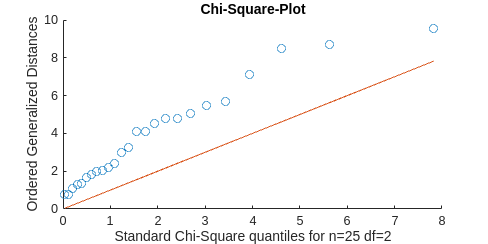

% QUESTION: can we just do chi-square plot with 2 degrees of freedom or
% we have to do 3d plot with 6 possible combinations and compute some kind
% of correlation coefficient? Because when df=2 looks quite bad, while with
% df=4 is almost perfect fit.
cla; clf;
chi_square_plot(data,2);


function d2 = generalized_squared_distances(data)
    x_bar = smean(data);
    S = sstd(data);
    d2 = diag((data - x_bar) / S * (data - x_bar)'); % \ equivalent to * inv(S)
end

function chi_square_plot(data, df)
    % the p parameter is an integer in the range(2,n) that considers how
    % many variables are analyzed jointly
    % Get shape of the data
    n = size(data,1);
    
    % Order the squared distances
    d2 = sort(generalized_squared_distances(data));
    
    % Get standard chi-square quantiles for all datapoints
    p = linspace(1/(2*n), 1-1/(2*n), n);
    q = chi2inv(p, df);

    set(gcf,'position',[0,0,2000,1000])

    % Scatter plot and ideal slope
    scatter(q, d2');
    title('Chi-Square-Plot');
    ylabel('Ordered Generalized Distances');
    xlabel(['Standard Chi-Square quantiles for n=' num2str(n) ' df=' num2str(df)]);
    hold on;
    plot(q, q); % p184 it should have a slope of 1 for comparison
    hold off;
end

### c) Compute a chi-squared plot for all 4 dimensions considered together.

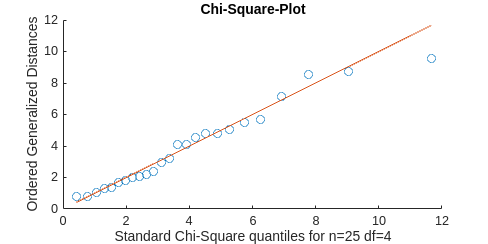

cla; clf;
chi_square_plot(data,4);

### d) Identify possible outliers. If one or more outliers are found, concisely discuss what shall be done with it/them.

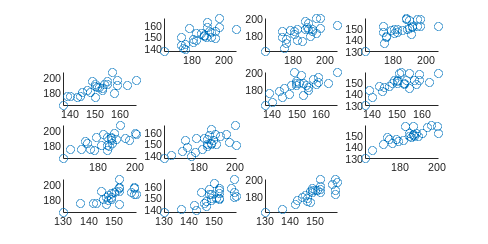

% Steps

% Make dot plot for each variable

% Make scatter plots for each pair of variables
scatter_all(data)


% Calculate and analyze standardized values (relative to size of dataset)

% Examine high values in chi-squared plot

function scatter_all(data)
    [n, dims] = size(data);

    for i=1:dims
        for j=1:dims
            if i == j
                continue
            end
            subplot(dims, dims, (i-1)*dims+j);
            scatter(data(:,i), data(:,j));
        end
    end
end

### e) Based on all the above information, indicate whether you would find it acceptable to test this dataset using statistical techniques that assume the data following an (approximately) multivariate normal distribution. Make a clear and concise justification of your answer.

## PROBLEM 14

File SM22_Seminar_2_Alcohol_and_Tobacco.xlsx contains data from 200 cases of oesophageal cancer and 775 controls. For each subject, the table provides his/her alcohol and tobacco consumption, indicated in grams per day. We want to test whether the average alcohol and tobacco consumption (combined as bivariate samples) are significantly higher in subjects that developed oesophageal cancer than they are in controls.

### a) State the null and alternative hypotheses to be tested (make sure to include the mathematical formulation).

### b) Inspect your data for multivariate normality. Clearly indicate whether you would advise in favor or against using statistical methods that assume multivariate normality in these data.

### c) Based on your conclusions in (b), test the hypotheses stated in (a) at significance level α = 0.05. Indicate what conclusion you reach.

### d) Calculate and plot a 95% confidence region for the difference of (alcohol, tobacco) consumption between cancer cases and controls. Show that it conforms with the conclusion in (c).

## PROBLEM 15

File SM22_Seminar_2_Height_and_Weight.xlsx contains data from men and women engaged in regular exercise. Each subject was asked to self-report his/her height and weight. Actual values of height and weight were also measured. We are interested in the following question: on average, do men and women differ in the bias with which they perceive their body height and weight (considered jointly)?

### a) Inspect the data and discuss what dimensions shall be used and in what manner (e.g. as provided, added, multiplied, ...). State the appropriate null and alternative hypotheses.

### b) Assess whether your data (or the relevant subsets) can be analyzed under the assumption of multivariate normality. If you find that this is not the case, propose and implement some solution. Carefully justify your choice.

### c) Test the null hypothesis at significance level α = 0.05. Clearly indicate and justify the statistic you choose. Indicate your conclusion.

### d) Compute 95% confidence intervals for the bias in perceived height and for the bias in perceived weight. Since we are analyzing multivariate data, the intervals should hold simultaneously at the specified confidence level.

## PROBLEM 16

Given the 4-dimensional random sample from file SM22_Seminar_2_4d.xlsx, inspect the data to determine if it0 follows a multivariate normal distribution.

### a) Indicate graphically if each of the dimensions is normally distributed.

### b) Indicate graphically if each pair of dimensions is normally distributed.

### c) Compute Q-Q plots for each dimension.

### d) Compute a chi-squared plot for all dimensions considered together.

### e) Use the above plots to look for outliers.

### f) Based on all the above information, indicate whether you would find acceptable to test this dataset using statistical techniques that assume the data following an (approximately) multi-variate normal distribution.

## PROBLEM 17

File SM22_Seminar_2_Plants.xlsx contains data samples from 2 types of plants. Each row of the file contains one sample, for which there are 5 columns, as follows: i) type of plant (1 or 2); ii) sepal length; iii) sepal width; iv) petal length; v) petal width. We want to test if the two types of plants have different mean in terms of these 4 variables that have been measured, using Hotelling’s T².

### a) State the null and alternative hypotheses to be tested.

### b) Inspect the data and indicate whether it fulfills the assumptions necessary to use Hotelling’s T² (independence of the random samples can be assumed).

#### b1. Test the assumptions of multivariate normality.

#### b2. Inspect (roughly) the assumption of equality of covariances.

### c) Based on your conclusions in (b), determine if any of the T² statistics discussed in class could be employed to test the hypotheses in (a). Hint: If none is suitable, try transforming one or more variables. If you cannot find a satisfactory transformation, you can remove the dimension(s) that prevent your data from meeting the assumptions required to apply Hotelling’s T².

### d) Test the hypothesis indicated in (a) at α = 0.05 significance level and indicate what is the conclusion.